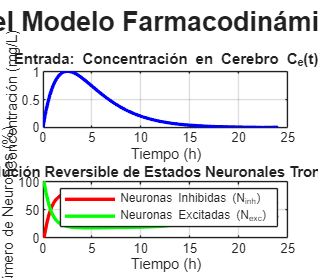

%% SIMULACIÓN DEL MODELO FARMACODINÁMICO MECANICISTA (REVERSIBLE)
%--------------------------------------------------------------------------
% Este script simula el modelo dN/dt incluyendo un término de 
% recuperación, lo que permite que el efecto del fármaco sea reversible.
%--------------------------------------------------------------------------

clear;
clc;
close all;

%% 1. Parámetros del Modelo (Ajustados Científicamente)
N_tot = 100;         % % de la población neuronal total
Kd    = 0.03303;     % mg/L (Sensibilidad, análogo a EC50)
beta  = 1.2;         % 1/h  (Tasa máxima de inhibición)
alpha = 0.25;         % 1/h  (Tasa de recuperación natural)

%% 2. Simulación de la Entrada (Curva de Concentración PK)
t_final = 24; % horas
dt = 0.1;   % horas
t = 0:dt:t_final;

% Curva de concentración Ce(t) simulada
Ce_t = 1.1 * t .* exp(-0.4 * t); % Concentración (mg/L)

%% 3. Bucle de Simulación Numérica (Resolviendo la Ecuación Diferencial)
% Inicializamos los vectores de estado
N_inh = zeros(size(t));
N_exc = zeros(size(t));
N_exc(1) = N_tot;

% Bucle 'for' para resolver la ecuación paso a paso
for i = 1:length(t)-1
    % Valor actual de la concentración y del estado
    C_i = Ce_t(i);
    N_inh_i = N_inh(i);
    
    % Calcular los dos términos de la ecuación
    termino_inhibicion = beta * (C_i / (Kd + C_i)) * (N_tot - N_inh_i);
    termino_recuperacion = alpha * N_inh_i;
    
    % La derivada es la diferencia entre inhibición y recuperación
    dN_inh_dt = termino_inhibicion - termino_recuperacion;
    
    % Actualizar el estado para el siguiente instante de tiempo
    N_inh(i+1) = N_inh_i + dN_inh_dt * dt;
    
    % Asegurarse de que el estado no sea negativo por errores numéricos
    if N_inh(i+1) < 0
        N_inh(i+1) = 0;
    end
    
    % Actualizar el número de neuronas excitadas
    N_exc(i+1) = N_tot - N_inh(i+1);
end

%% 4. Visualización de Resultados
figure('Position', [100, 100, 800, 700]);
sgtitle('Simulación del Modelo Farmacodinámico Reversible', 'FontSize', 16, 'FontWeight', 'bold');

% Gráfica 1: Entrada de Concentración
subplot(2,1,1);
plot(t, Ce_t, 'b-', 'LineWidth', 2);
title('Entrada: Concentración en Cerebro C_e(t)');
xlabel('Tiempo (h)');
ylabel('Concentración (mg/L)');
grid on;

% Gráfica 2: Transición de Estados Neuronales
subplot(2,1,2);
plot(t, N_inh, 'r-', 'LineWidth', 2);
hold on;
plot(t, N_exc, 'g-', 'LineWidth', 2);
title('Salida: Evolución Reversible de Estados Neuronales Tronco encefálico');
xlabel('Tiempo (h)');
ylabel('Número de Neuronas (%)');
legend('Neuronas Inhibidas (N_{inh})', 'Neuronas Excitadas (N_{exc})');
grid on;